% Create individual element
fc = 915e6;
c = physconst('lightspeed');
lambda = c/fc;

dx = 0.5*lambda;  %0.485
d = phased.ShortDipoleAntennaElement(...
    'FrequencyRange',[902e6 928e6],'AxisDirection','Z');
N = 4;

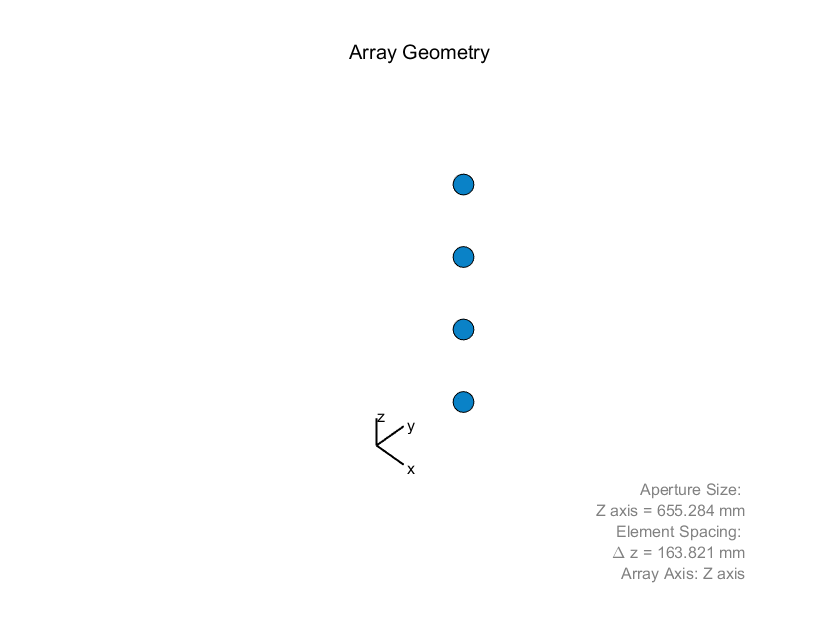

% Create array
array = phased.ULA;
array.Element = d;
array.ElementSpacing = dx;
array.NumElements = N;
array.ArrayAxis = 'z';
viewArray(array);

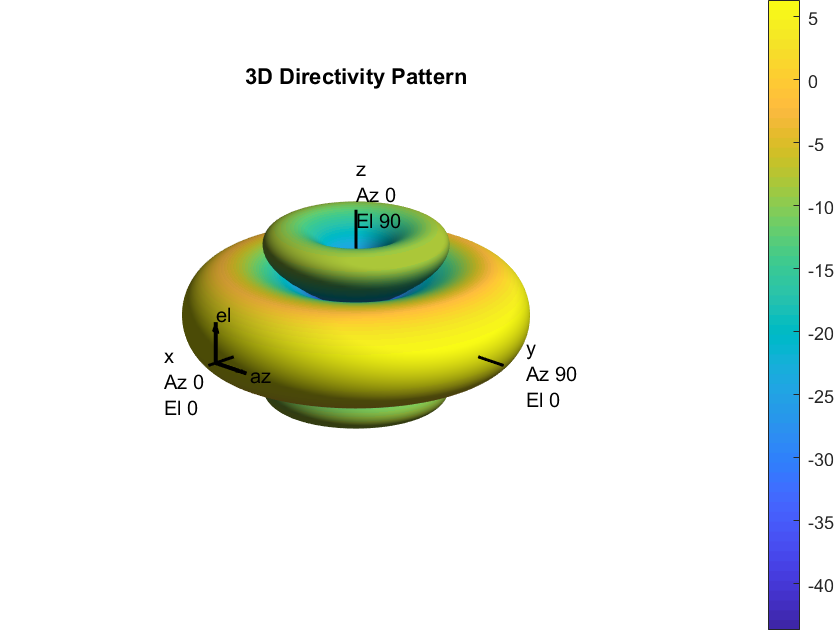

pattern(array,fc);

% sterring vector
steervec = phased.SteeringVector('SensorArray',array);
ang = [120; -45]; % 0 azimuth, 45 elevation
sv = steervec(fc,ang);

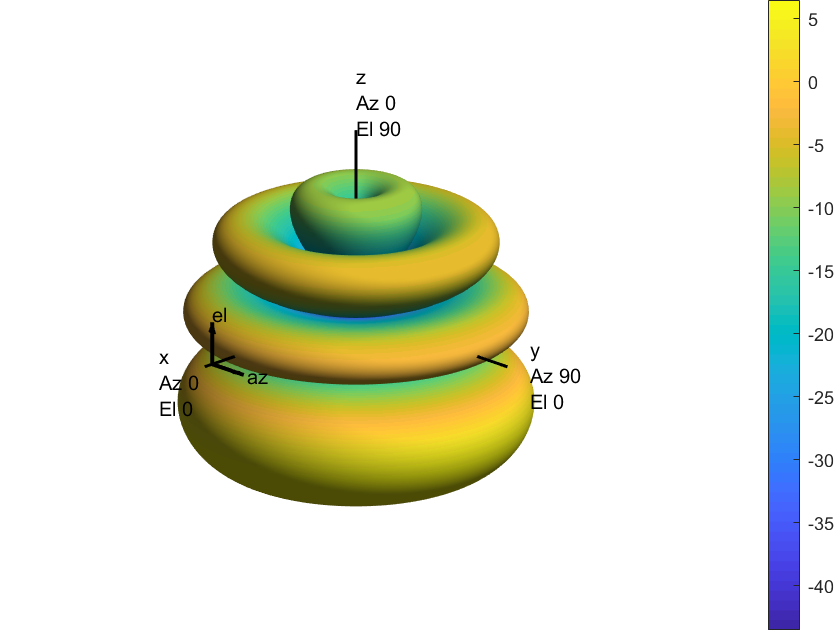

pattern(array,fc,'Weights',sv)

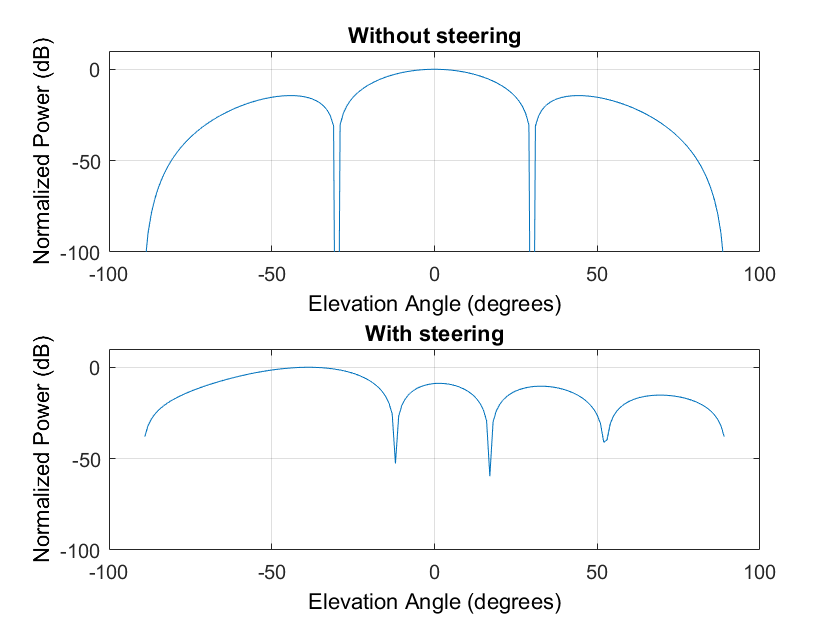

subplot(211)
pattern(array,fc,0, -90:90,'CoordinateSystem','rectangular', ...
    'PropagationSpeed',c,'Type','powerdb')
title('Without steering')
subplot(212)
pattern(array,fc,0, -90:90,'CoordinateSystem','rectangular', ...
    'PropagationSpeed',c,'Type','powerdb','Weights',sv)
title('With steering')